# README

## Files and directories

The project is organized as foolows in a *root* folder:

% root
% ├ Data
% │  ├ g4dmemf12.avi
% │  ├ g4dmemf12-3.avi
% │  ...
% │  └ g4gcb-2.avi
% ├ Figures
% ├ Files
% ├ Movies
% └ Programs

*root* can be anywhere in your filesystem (*e.g.* `/home/Me/Science/Projects/Pillars`). The folders are as follows:

- `Data` is where the video files should be put. Videos can have any name, and may be grouped in folders and subfolders. Other files with the same names but different extensions may then be created during image processing, this is a normal procedure; the original video remain unaltered, but having a copy somewhere else as a backup is always a good paractice. `Data` can also be a link to a remote storage folder.

- `Files` contains intermediary and output files (`drift.mat`, `trajectories.mat`, etc.). Normally one does not have to do anything there, the content is automatically created and read. It is directly mirroring the tree structure of the `Data` folder.

- `Programs` contains all the scripts and functions and classes, but no data of any kind. It is this folder that should be synchronized with the Github repository.

- `Figures` and `Movies `contains materials, that can be anything the user wants to create. It does not necessaritly mirrors the structure of the `Data` folder.

### Install setup

In order to let the programs know where to search for the different elements, the *root *path has to be included in the following piece of code in the `root``/Programs/@Focus/Focus.m` file, inside the `getRoot` static method (line ~150):

switch computer

    case 'PCWIN64'  % Windows
        test = {};

    case 'GLNXA64'  % Linux
        test = {'/home/ljp/Science/Projects/Misc/Pillars/' ...
            '/home/raphael/Science/Projects/Misc/Pillars/'};

    case 'MACI64'   % Mac
        test = {};

end

The *root *path has to be specified in a string of the cell `test` in the appropriate section corresponding to your OS. All pathes in `test` will then be tested and as soon as one is found, it is considered as the *root*. Other pathes are simply ignored. This architecture allows to run the project flawlessly on multiple machines.

You can check that your machine is correctly configured when the *root* path is actually the output of the following command line:

Focus.getRoot

ans = '/home/raphael/Science/Projects/Misc/Pillars/'

## Focus

Inside the code, the `Focus` object is the entry point for interacting with the data. It is simply defined with:

F = Focus('g4dmemf12');

=== g4dmemf12 =========================


where the first input is a *tag* string containing the identifier of the dataset to focus on. The *tag *can contain filesystem separators (`/` or `\`) to include subdirectories.

NB: verbose can be turned off with

F = Focus('g4gcb', verbose=false);

A list of all available tags can be obtained with the static method `Focus.taglist`:

L = Focus.taglist()

L = 1×8 cell array
    {'BY'}    {'BY2'}    {'g4-2'}    {'g4dmemf12'}    {'g4dmemf12-3'}    {'g4dmemf12-4'}    {'g4gcb'}    {'g4gcb-2'}


## Image processing

The code for tracking the pillars is contained in the `+IP` package. The typical routine is embed in the `IP.Routine` script.

A `pTracker` object is created, and the following methods are called sequentially:

- *Initial search*: locate pillars in the first image based on correlation with the average pillar shape. A kernel size `ks` smaller than the one used for the tracking is preferable. A filter based on the value of the correlation is applied (set by the `minCorr` parameter).

- *Defining kernels*: kernels are taken large enough to encompass the whole pillar and a watershed algorithm is used to remove parts of other pilars that may appear at the boundaries.

- *Tracking*

- *Cleaning: *Some trajectories contain `NaN` values, typically at the borders of the image or when convolution failed. Their `checked` flag is then turned to `false`.

The result of the tracking is contained in the `pTracker``.P` property and is saved in the file `Focus``.File.trajectories` mat-file (located under the `Root``/Files/` folder). `P` is a structure vector where each element represents a pillar and has the following fields:

- `x        `The x-coordinate trace (vector)

- `y        `The y-coordinate trace (vector)

- `c0       `The value of the correlation with the average kernel shape during the inital searching step (scalar)

- `K        `The corresponding kernel (array)

- `checked  `A boolean flag used to filter the pillars kept during subsequent analysis (scalar). `true` means that the pillar is kept, while `false` means it is discarded.

## Post-processing selection

The `GUI.Selector` object allows to visualy check the quality of the tracking, manually define the pillars selected for subsequent analysis and to define a new pillar or re-define a kernel asociated to a pillar and perform a new tracking over this single pillar.

GUI.Selector(F);

Shortcuts:

- `left click        `On the global panel, selects the current pillar.

- `middle click `or` z`: Toggle zoom state (global and trace panels)

- `right click       `Toggle `checked` state of the nearest pillar (global panel) or of the current pillar (other panels)

- `b         `Toggle baseline view

- `k         `Toggle kernel wiew for the current pillar

- `p         `Define a polygon and perform an action. On the global view the action is to toggle the `checked` state of the englobed pillars while on the kernel view it redefines the kernel of the current pillar.

- `r         `Run the tracking for the current pillar (erase the previous trajectory).

- `Ctrl+s    `Save the modified trajectories. **This is mandatory to modify the content of **`Focus``.Files.trajectories`** ! **Otherwise the modifications are lost upon exit.

- `Escape    `Quit (close the GUI)       

## Events detection

Events detection is handled by the `Analysis.Detector` class. There is a routine script to make event detection straightforward:

Analysis.Routines.Detection

It automatically creates a `Detector` object and performs several actions:

- The events are detected by simple thresholding of the checked pillars (`Detector.detect` method).

- Comptutation of the skewness (asymmetry) of the events (`Detector.skewness` method)

- Fit of all the events (`Detector.fitAllEvents` method). This is the longer part.

- Save the events in the `Events.mat `file of the `Focus``.Dir.Files` folder

## Checking and filtering the events

The `GUI.Filters `object allows to check many aspects of the detected events.

Computing ... 

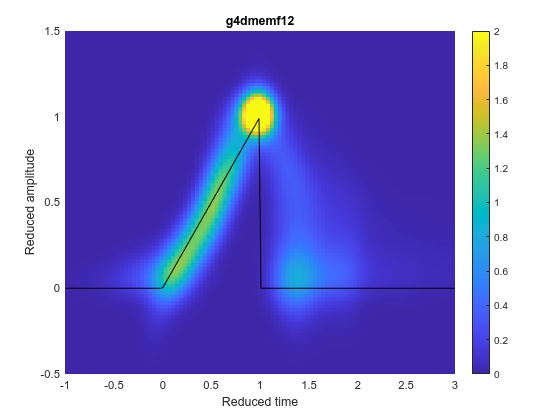

GUI.Filters;

- The `Events` tab lets you inspect the events detected on traces of the pillars in the image

- The `Filters` tab allows to display the distributions of the different features of the events (slope, amplitude, stauration, etc.). It can display bivariate distribution (by selecting 2 rows) or scatter plots for 3 parameters (by selecting 3+ rows). One can filter out the events outside of a given range for each parameter and obtain both the marginal distribution or the globally filtered distribution of this parameters.

### Exporting filtered events

The filtered events can be exported using the `Export` options in the menu bar:

- `to workspace`: A structure called `Events` is saved to the workspace.

- `to file`: The user is prompted for a location to save the file. The exported mat file contains the same `Events` structure.

To extract a vector of a given property out of the generated `Events` structure, the following syntax can be used:

Amp = [Events(:).A];    % For amplitude
% One can then obtain further info with min(Amp), max(Amp), mean(Amp), etc.

## Other plots

Script located in the `Analysis.Figure` package can be used to further characterize the data.

For instance:

Analysis.Figures.density_reduced_shape  